R1 = 2609

R1 = 2609

R2 = 13809

R2 = 13809


C = 266 * 10^(-6)

C = 2.6600e-04


T_ = C * R1

T_ = 0.6940

k = R2 / R1

k = 5.2928


t = linspace(0, 10)

t =          0    0.1010    0.2020    0.3030    0.4040    0.5051    0.6061    0.7071    0.8081    0.9091    1.0101    1.1111    1.2121    1.3131    1.4141    1.5152    1.6162    1.7172    1.8182    1.9192    2.0202    2.1212    2.2222    2.3232    2.4242    2.5253    2.6263    2.7273    2.8283    2.9293    3.0303    3.1313    3.2323    3.3333    3.4343    3.5354    3.6364    3.7374    3.8384    3.9394    4.0404    4.1414    4.2424    4.3434    4.4444    4.5455    4.6465    4.7475    4.8485    4.9495



y_ir = sign(t + 0.01) / T_

y_ir =     1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409    1.4409



num_i = [T_ * k 1];
den_i = [T_ 0];
sys_i = tf(num_i, den_i);

y_sr = t / T_ + k

y_sr =     5.2928    5.4384    5.5839    5.7295    5.8750    6.0206    6.1661    6.3117    6.4572    6.6028    6.7483    6.8939    7.0394    7.1850    7.3305    7.4761    7.6216    7.7672    7.9127    8.0583    8.2038    8.3494    8.4949    8.6405    8.7860    8.9316    9.0771    9.2227    9.3682    9.5138    9.6593    9.8049    9.9504   10.0959   10.2415   10.3870   10.5326   10.6781   10.8237   10.9692   11.1148   11.2603   11.4059   11.5514   11.6970   11.8425   11.9881   12.1336   12.2792   12.4247



num_s = [T_ * k 1];
den_s = [T_ 0 0];
sys_s = tf(num_s, den_s);


%{
plot(t, y_ir, 'c', LineWidth=1.5)
hold on
impulse(sys_i, 'k--')
legend('U_{i.r.} - аналитика', 'U_{i.r.} - симуляция')
title('Весовая функция для регулятора на операционном усилителе.')
grid()
ylabel("f(t)")
xlabel('t')
xlim([0 5])
hold off



plot(t, y_sr, 'c', LineWidth=1.5)
hold on
impulse(sys_s, 'k--')
legend('U_{s.r.} - аналитика', 'U_{s.r.} - симуляция')
title('Переходная функция для регулятора на операционном усилителе')
grid()
ylabel("f(t)")
xlabel('t')
xlim([0 5])
ylim([0 15])
hold off

%}
w = linspace(0, 1000)

w = 1.0e+03 *

         0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949


%{
ach = sqrt(k^2 + (1 ./ (T_^2 * w .* w)))
%phi = 

figure('Position', [1000 0 800 450])
plot(w, ach, LineWidth=1.5)

grid("on")
ylabel('A')
xlabel('\omega, rad/s')
legend('АЧХ')
ylim([0 25])
title('Амплитудно-частотная характеристика')
%}

%phi = atan2(-1 ./ (T_ * w), k) * 180 / pi
phi1 = 20 * log10(log10(exp(1)) * (atan2(-1 ./ (T_ * w), k)))

phi1 =   -3.3219 +27.2875i -38.6346 +27.2875i -44.6536 +27.2875i -48.1751 +27.2875i -50.6738 +27.2875i -52.6120 +27.2875i -54.1956 +27.2875i -55.5345 +27.2875i -56.6943 +27.2875i -57.7174 +27.2875i -58.6325 +27.2875i -59.4604 +27.2875i -60.2161 +27.2875i -60.9114 +27.2875i -61.5551 +27.2875i -62.1543 +27.2875i -62.7149 +27.2875i -63.2415 +27.2875i -63.7379 +27.2875i -64.2076 +27.2875i -64.6531 +27.2875i -65.0769 +27.2875i -65.4809 +27.2875i -65.8670 +27.2875i -66.2367 +27.2875i -66.5913 +27.2875i -66.9320 +27.2875i -67.2598 +27.2875i -67.5757 +27.2875i -67.8804 +27.2875i -68.1749 +27.2875i -68.4597 +27.2875i -68.7355 +27.2875i -69.0028 +27.2875i -69.2621 +27.2875i -69.5138 +27.2875i -69.7585 +27.2875i -69.9965 +27.2875i -70.2282 +27.2875i -70.4538 +27.2875i -70.6737 +27.2875i -70.8882 +27.2875i -71.0975 +27.2875i -71.3019 +27.2875i -71.5015 +27.2875i -71.6967 +27.2875i -71.8876 +27.2875i -72.0744 +27.2875i -72.2573 +27.2875i -72.4364 +27.2875i




figure('Position', [1000 0 800 450])

plot(w, phi1, 'LineWidth', 1.5,'DisplayName', 'ФЧХ')

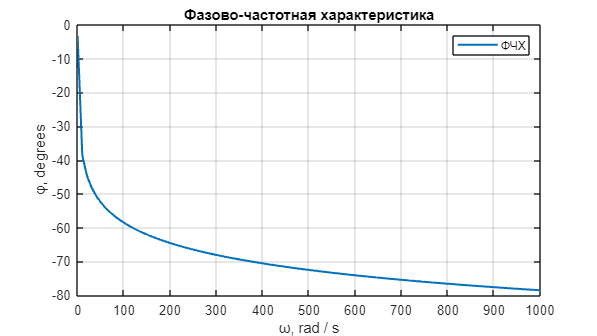

%semilogx(w, phi)
title('Фазово-частотная характеристика')
legend()
ylabel('φ, degrees')
xlabel('ω, rad / s')
%ylim([-200 20])
grid("on")




figure('Position', [1000 0 800 450])
ops = bodeoptions;
ops.Title.String = 'ЛАФЧХ'

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

ops.Title.FontSize = 15

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

ops.XLabel.FontSize = 12

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

ops.YLabel.FontSize = 12

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

   
h = bodeplot(sys_i, 'c', ops)


h =

	resppack.bodeplot



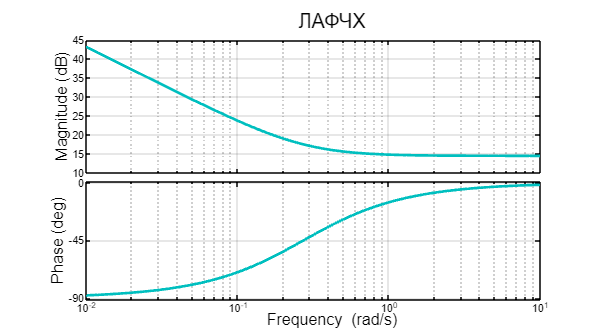

grid on;
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2);